# System Identification (GPC)

## 1. Load + format data

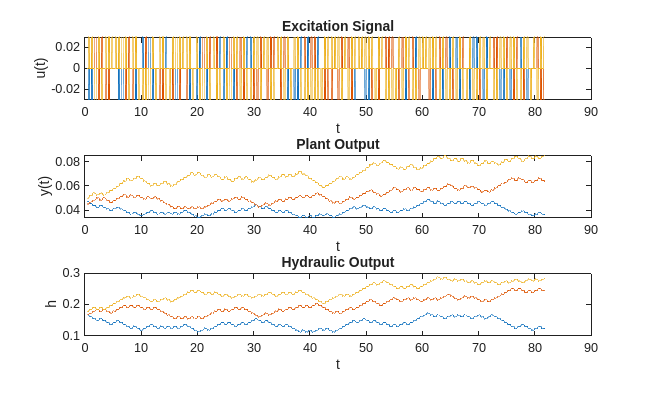

data_path = fullfile("data", "IdMPC0.1728_est.mat");
Ts = 0.02;
load(data_path);
% Drop the first sample
startIdx = 20;
t = t(startIdx:end, :);
u = u(startIdx:end, :);
y = y(startIdx:end, :);
l_hy = l_hy(startIdx:end, :);

figure;
subplot(3, 1, 1);
plot(t, u);
title('Excitation Signal'); xlabel('t'); ylabel('u(t)');
subplot(3, 1, 2);
plot(t, y);
title('Plant Output'); xlabel('t'); ylabel('y(t)');
subplot(3, 1, 3);
plot(t, l_hy);
title('Hydraulic Output'); xlabel('t'); ylabel('h');

## 2. Create `iddata` + detrend

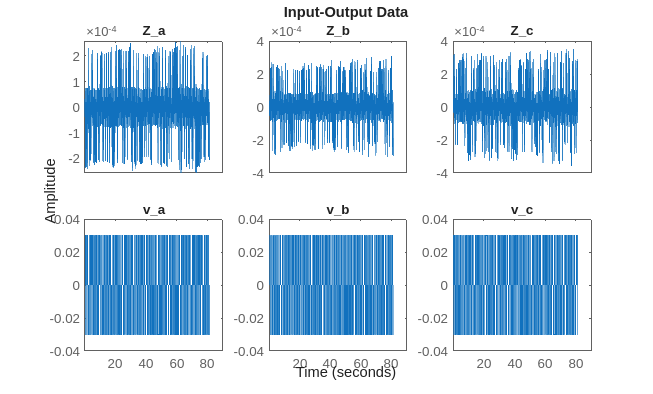

y = diff(y);
u = diff(u);

data = iddata(y, u, Ts, "TimeUnit", "s");
data.InputName = {"v_a", "v_b", "v_c"};
data.OutputName = {"Z_a", "Z_b", "Z_c"};

% remove mean
% data = detrend(data, 0);

figure;
idplot(data);

## 3. Split estimation/validation

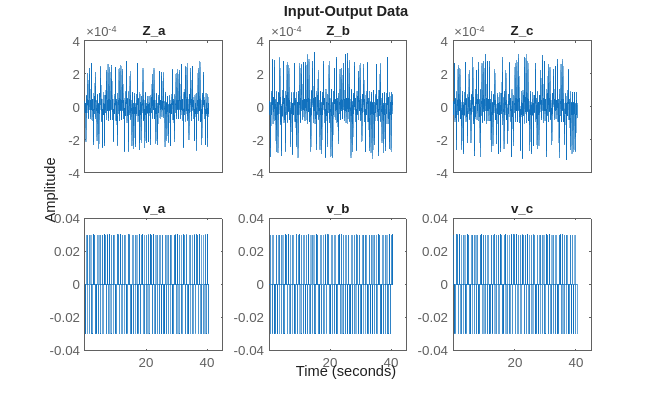

% N = size(data.OutputData, 1);
% Ne = floor(0.7*N);
% 
% data_est = data(1:Ne);
% data_val = data(Ne+1:end);

data_est = data;
data_path = fullfile("data", "IdMPC0.1728_val.mat");
load(data_path);
t = t(startIdx:end, :);
u = u(startIdx:end, :);
y = y(startIdx:end, :);
l_hy = l_hy(startIdx:end, :);

u = diff(u);
y = diff(y);

data_val = iddata(y, u, Ts, "TimeUnit", "s");
data_val.InputName = {"v_a", "v_b", "v_c"};
data_val.OutputName = {"Z_a", "Z_b", "Z_c"};
figure;
idplot(data_val);

## 4. Estimate CARIMA model

y_est = data_est.y;
u_est = data_est.u;
y_val = data_val.y;
u_val = data_val.u;

n_a = 2:10; n_b = 1:10;
d = 0;

fit_best = -Inf;
a_best = 0; b_best = 0;
for na = n_a
    for nb = n_b
        p = na + nb + 1;
        S = zeros(3 * p,3 * p);
        rhs = zeros(3 * p,3);
        k0 = max(na, nb + d + 1) + 1;
        for k = k0 : size(y_est, 1)
            phi_y = -y_est(k - 1 : -1 : k - na, :).';            % 3 x n_a
            phi_y = phi_y(:);                                % 1 x (3 * n_a)
            phi_u = u_est(k - 1 - d : -1 : k - 1 - d - nb, :).'; % 3 * (n_b + 1)
            phi_u = phi_u(:);                                % 1 x (3 * (n_b + 1))
            phi = [phi_y; phi_u];                            % (3 * p) x 1
            S = S + phi * phi';
            rhs = rhs + phi * y_est(k, :);
        end
        theta_hat = S \ rhs;

        Phi = [];
        for k = k0 - 1 : -1 : k0 - na
            Phi = cat(2, Phi, -y_val(k : end - (k0 - 1 - k) - 1, :));
        end
        for k = k0 - 1 : -1 : k0 - 1 - nb
            Phi = cat(2, Phi, u_val(k : end - (k0 - 1 - k) - 1, :));
        end
        y_hat = Phi * theta_hat;

        fit = 100 * (1 - norm(y_val(k0:end, :) - y_hat) / ...
            norm(y_val(k0+1:end, :) - mean(y_val(k0+1:end, :))));
        fprintf("n_a=%d, n_b=%d, fit=%.2f\n", na, nb, fit);
        if fit > fit_best + 0.1
            fit_best = fit;
            theta_best = theta_hat;
            na_best = na;
            nb_best = nb;
        end
    end
end

n_a=2, n_b=1, fit=90.60
n_a=2, n_b=2, fit=90.92
n_a=2, n_b=3, fit=92.50
n_a=2, n_b=4, fit=93.43
n_a=2, n_b=5, fit=93.75
n_a=2, n_b=6, fit=93.77
n_a=2, n_b=7, fit=93.93
n_a=2, n_b=8, fit=94.55
n_a=2, n_b=9, fit=95.32
n_a=2, n_b=10, fit=95.69
n_a=3, n_b=1, fit=94.54
n_a=3, n_b=2, fit=96.02
n_a=3, n_b=3, fit=99.30
n_a=3, n_b=4, fit=99.46
n_a=3, n_b=5, fit=99.46
n_a=3, n_b=6, fit=99.46
n_a=3, n_b=7, fit=99.46
n_a=3, n_b=8, fit=99.46
n_a=3, n_b=9, fit=99.46
n_a=3, n_b=10, fit=99.46
n_a=4, n_b=1, fit=95.42
n_a=4, n_b=2, fit=96.89
n_a=4, n_b=3, fit=99.48
n_a=4, n_b=4, fit=99.55
n_a=4, n_b=5, fit=99.56
n_a=4, n_b=6, fit=99.56
n_a=4, n_b=7, fit=99.56
n_a=4, n_b=8, fit=99.56
n_a=4, n_b=9, fit=99.56
n_a=4, n_b=10, fit=99.56
n_a=5, n_b=1, fit=95.73
n_a=5, n_b=2, fit=97.12
n_a=5, n_b=3, fit=99.48
n_a=5, n_b=4, fit=99.57
n_a=5, n_b=5, fit=99.59
n_a=5, n_b=6, fit=99.60
n_a=5, n_b=7, fit=99.60
n_a=5, n_b=8, fit=99.60
n_a=5, n_b=9, fit=99.60
n_a=5, n_b=10, fit=99.60
n_a=6, n_b=1, fit=95.79
n_a=6, n_b=2


fprintf("Best n_a = %d, n_b = %d, fit = %.2f", na_best, nb_best, fit_best);

Best n_a = 4, n_b = 5, fit = 99.56

## 5. Validate the model

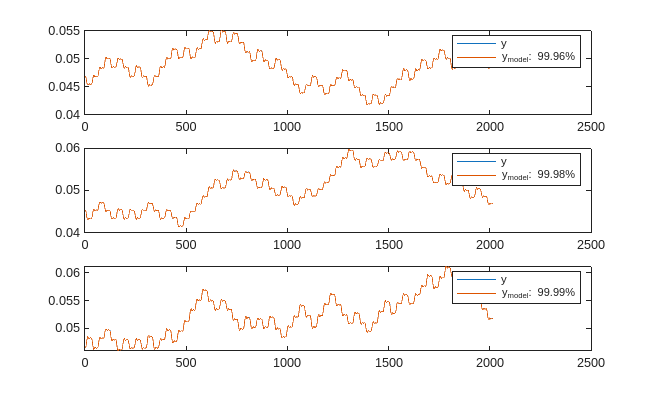

y = data_val.y;
u = data_val.u;

Phi = [];
for k = k0 - 1 : -1 : k0 - na_best
    Phi = cat(2, Phi, -y(k : end - (k0 - 1 - k) - 1, :));
end
for k = k0 - 1 : -1 : k0 - 1 - nb_best
    Phi = cat(2, Phi, u(k : end - (k0 - 1 - k) - 1, :));
end

y_hat = Phi * theta_best;
% figure;
% for i = 1 : 3
%     subplot(3, 1, i);
%     plot(t_ds(k0+1:end), [y(k0:end, i) y_hat(:, i)]);
% end

load("data/IdMPC0.1728_val.mat", "y");
y = y(startIdx:end, :);
y_model = y(k0, :) + cumsum(y_hat, 1);
figure;
for i = 1 : 3
    fit = 100 * (1 - norm(y(k0+1:end, i) - y_model(:, i)) / ...
        norm(y(k0+1:end, i) - mean(y(k0+1:end, i))));
    subplot(3, 1, i);
    plot(y(k0+1:end, i)); hold on;
    plot(y_model(:, i)); hold off;
    legend("y", sprintf("y_{model}: %.2f%%", fit));
end

## 6. GPC parameters

theta_best = reshape(theta_best', 3, 3, []);
A = cat(3, ones(3, 3), theta_best(:, :, 1:na_best));
B = theta_best(:, :, na_best+1:na_best+nb_best+1);

save("data/GPC_params.mat", "A", "B");